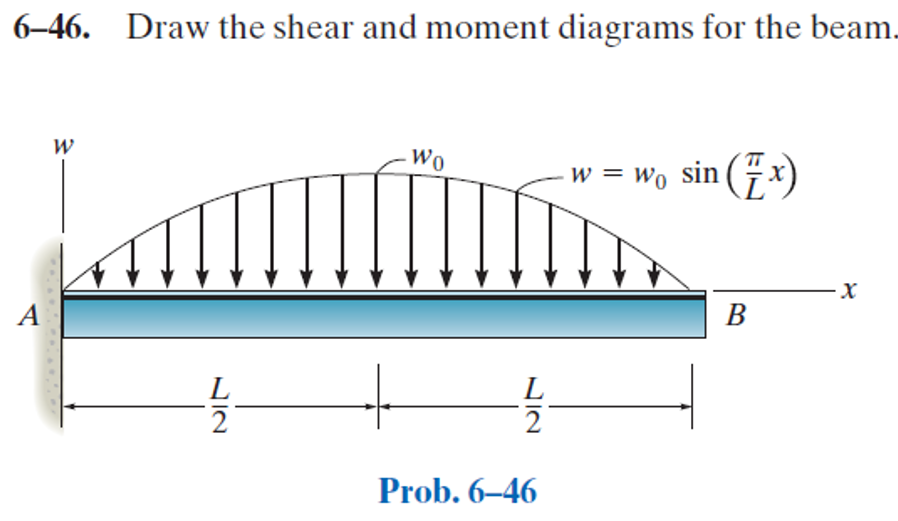

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-46P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-46P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# distributed load data

x = sym('x');
wo = sym('wo');
L = sym('L', 'positive');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('distributed', 'force', -wo*sin((sympi/L)*x), [0 L]);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = -\frac{L\,\mathrm{wo}\,\left(6\,L^{3}\,\sin\left(\frac{\pi \,x}{L}\right)-x^{3}\,\pi^{3}+3\,L\,x^{2}\,\pi^{3}-6\,\pi \,L^{2}\,x\right)}{6\,\text{E}\,\text{I}\,\pi^{4}}$$

dy

$$dy(x) = -\frac{L\,\mathrm{wo}\,\left(2\,L^{2}\,\cos\left(\frac{\pi \,x}{L}\right)-2\,L^{2}-x^{2}\,\pi^{2}+2\,L\,x\,\pi^{2}\right)}{2\,\text{E}\,\text{I}\,\pi^{3}}$$

m

$$m(x) = \frac{L\,\mathrm{wo}\,\left(\pi \,x+L\,\sin\left(\frac{\pi \,x}{L}\right)-\pi \,L\right)}{\pi^{2}}$$

v

$$v(x) = \frac{L\,\mathrm{wo}\,\left(\cos\left(\frac{\pi \,x}{L}\right)+1\right)}{\pi }$$

w

$$w(x) = -\mathrm{wo}\,\sin\left(\frac{\pi \,x}{L}\right)$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & \frac{L^{2}\,\mathrm{wo}}{\pi }\\ \mathrm{Ra} & \frac{2\,L\,\mathrm{wo}}{\pi } \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

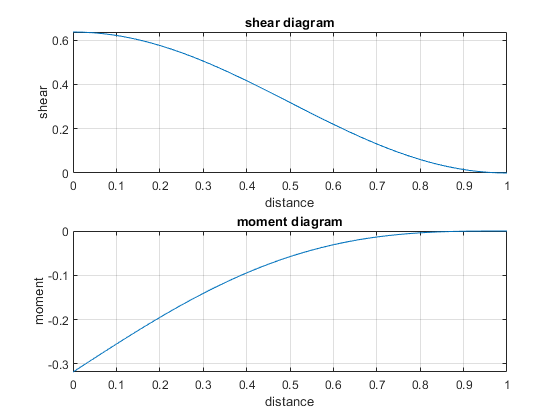

beam.shear_moment(m, v, [0 1], [wo L], 1);

# clean up

addvar(y);
new_assum = assumptions;